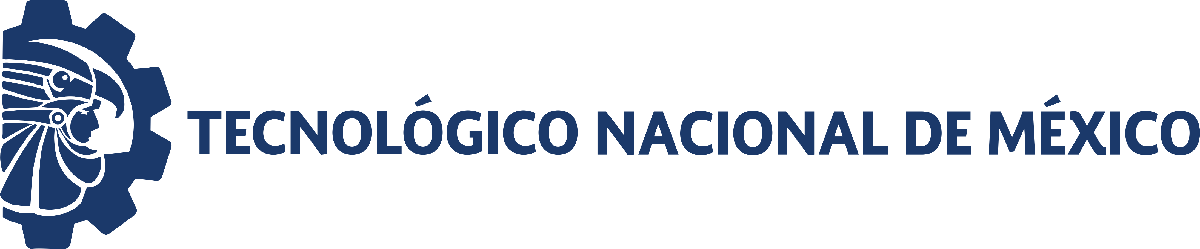                                 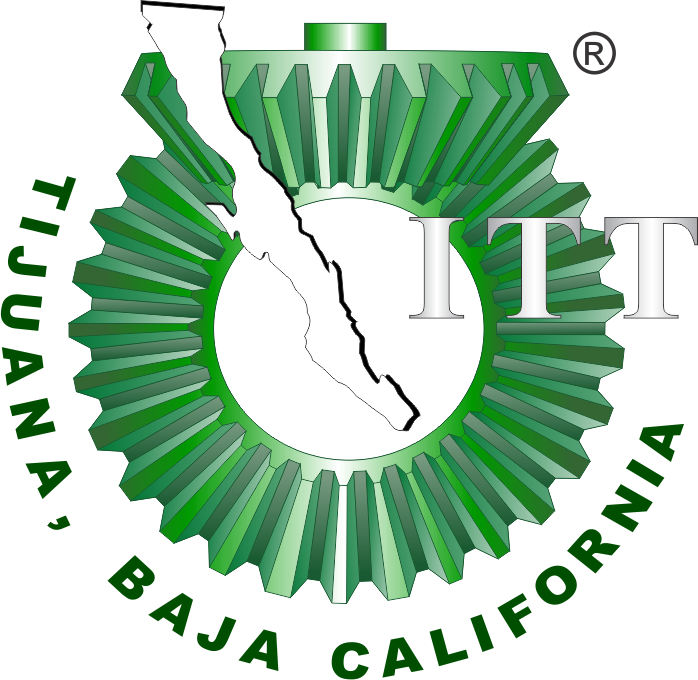

# Proyecto: Sistema Urinario (Insuficiencia Renal Aguda)

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

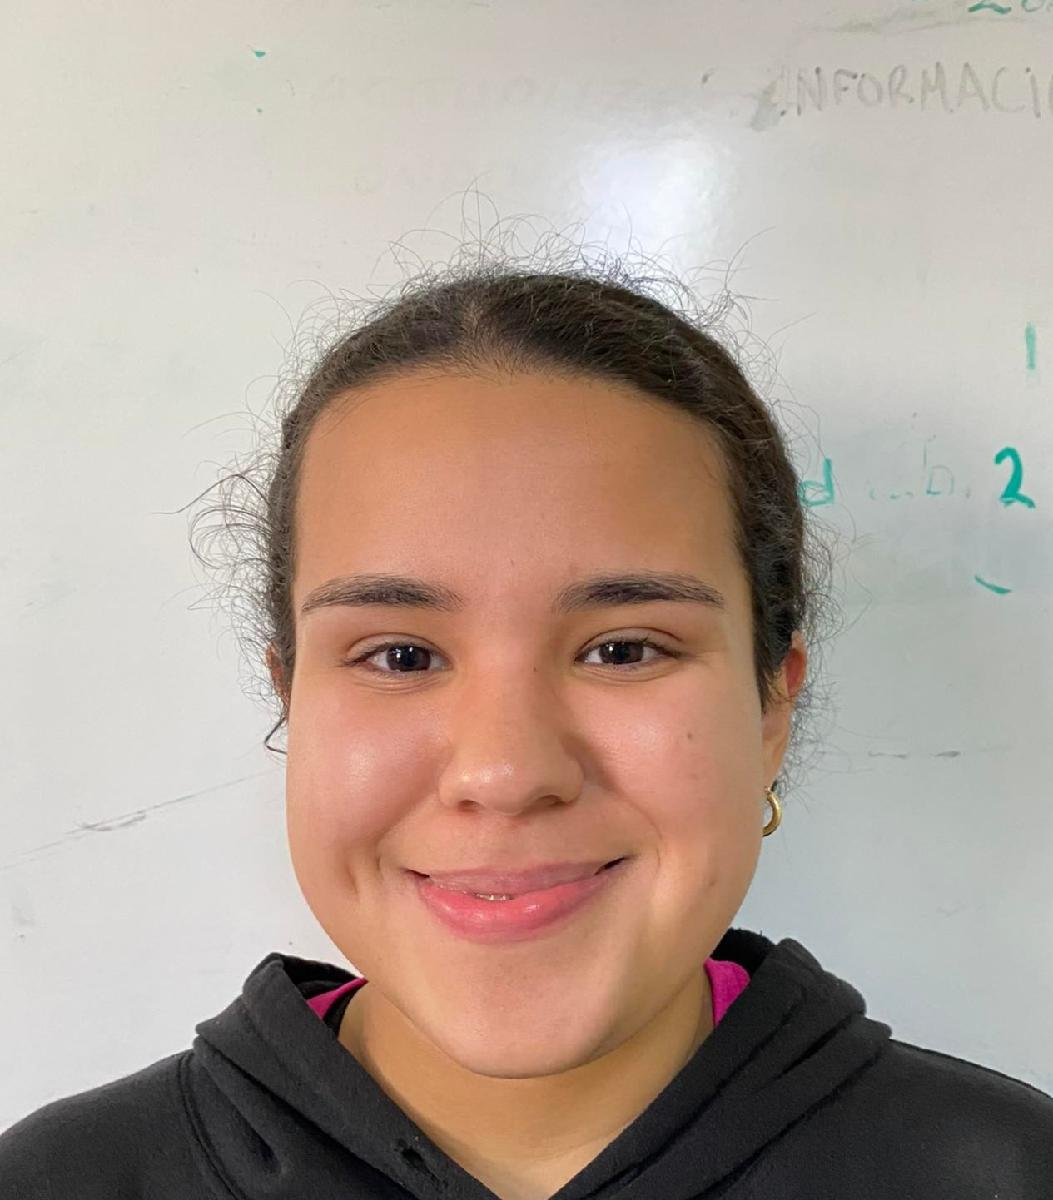  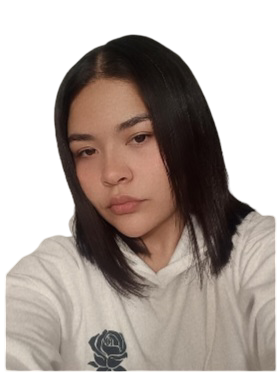

Nombre del alumno**: Rivera Peñuelas Mariana, Zamora Chon Michelle Ariadna**

Número de control:** 22210427, 22210432**

Correo institucional:** l22210427@tectijuana.edu.mx, l22210432@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaUrinarioPID';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15';
parameters.MaxStep = '1E-3';

## Respuesta a la función sinusoidal

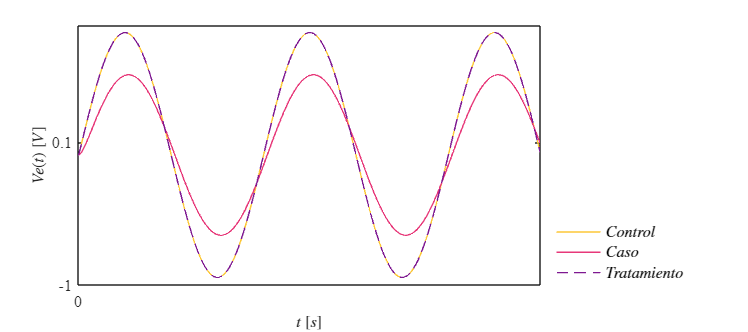

N = sim(file,parameters);
plotsignal(N.t,N.Ve,N.Vs,N.VPID)

## Funciones

function plotsignal(t,Ve,Vs,VPID)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    AMARILLO =[252/255, 199/255, 55/255];
    MORADO =[231/255, 56/255, 121/255];
    ROSA =[126/255, 24/255, 145/255];

    plot(t,Ve,'LineWidth',1,'Color', AMARILLO)
    plot(t,Vs,'LineWidth',1,'Color', MORADO)
    plot(t,VPID,'--','LineWidth',1,'Color', ROSA)

    L= legend('$Control$','$Caso$','$Tratamiento$');
    set(L,'interpreter','Latex','Fontsize',11,'Location','southeastoutside','Box','Off')

    xlabel('$t$ $[s]$', 'Interpreter','Latex','FontSize',11)
    ylabel('$Ve(t)$ $[V]$', 'Interpreter','Latex','FontSize',11)

     xlim([0, 10]); xticks(0:10.1:5)
     ylim([-1, 1]); yticks(-1:1.1:0.25)

    exportgraphics(gcf,['SistemaUrinarioIRA','.pdf'],'ContentType','vector')
    exportgraphics(gcf,['SistemaUrinarioIRA','.png'],'Resolution',600);
   
end
